## Bus Design Script

Load Bus configuration

% Initialize the model structure
clc; clear all;
% Load config struct for the Bus
bus = config_bus();
% Generate mass and stiffness tensors
bus = fem.generate_fem_matrices(bus);

Visualize to verify node/element configuration

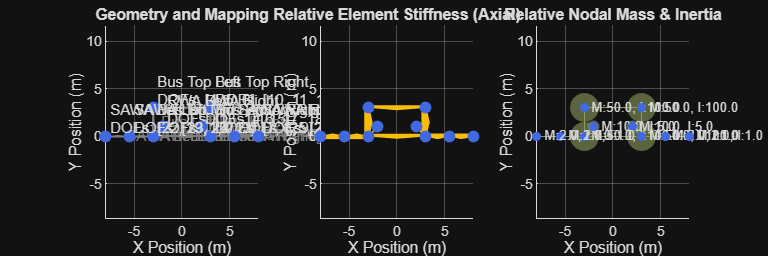

% Visualize the assembled FEM model
fem.plot_fem_model(bus);

Simulate disturbances from the RWAs

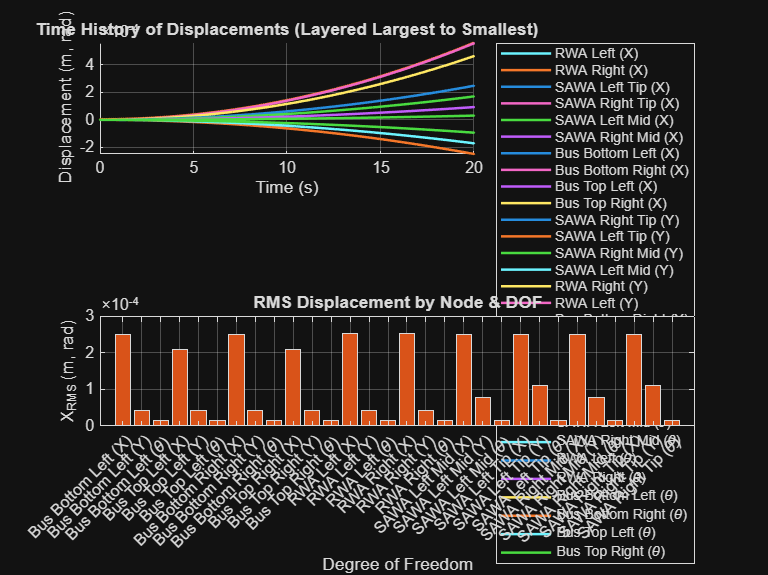

% Load options profile
options_rwa_disturbances = options_rwa_disturbances();
% Compute the spacecraft response under reaction-wheel disturbances
[X_rms_rwa_dist, X_rwa_dist] = fem.calculate_plot_rms(bus, options_rwa_disturbances);

Test Integration with the Isolator & Optical Bench

% Load config struct for the Isolator & Optical Bench
iso = config_Iso_Obench();
payload  = config_Payload();
% Generate mass and stiffness tensors
iso = fem.generate_fem_matrices(iso);
% Combine the structures
SV = fem.merge_fem_models(bus, iso, payload);

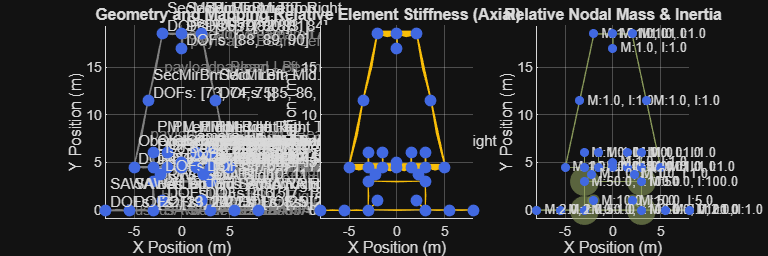

% Visualize the combined spacecraft FEM model
fem.plot_fem_model(SV);